%%Vehicle/Enivronment Parameters
Vehicle;

a = Vehicle;

%vehicle
a.Mass                  = 1000;                         %Mass           [kg]
a.friction_coef         = 0.03;                         %friction coefficient
a.gear_ratio            = 3;                            %gear ratio
a.wheel_radius          = 0.3;                          %wheel radius   [m]
a.Area_front            = 1.5;                          %frontal area   [m^2]
a.delta                 = 1+0.04+0.0025*a.gear_ratio^2;      %rotational inertia factor
a.efficiency            = 0.95;                         %efficiency
a.drag_coef             = 0.3;                          %drag coefficient
a.aero_efficiency       = 2.5;                          %cl/cd
a.AA                    = 30;                           %Active aero downforce in kg


v_max      =365/3.6;

%Environment
alpha   = 0;                        %inclination    [degrees]
V_kph   = 100;                      %Vehicle speed  [km/h]
V_ms    = V_kph/3.6;                %Vehicle speed  [m/s]
V_w_kph = 0;                        %Wind speed     [km/h]
V_w_ms  = V_w_kph *(1000/3600);     %Wind speed     [m/s]



% 
% %Calculation for maximum speed on a flat surface;
% 
%tractive force for maximum speed
F_maxspeed = tractive_force(0,v_max,0,a)

F_maxspeed = 3.5092e+03

P_maxspeed = F_maxspeed * v_max %this is about 350kW

P_maxspeed = 3.5580e+05

F_maxspeed = 3.5580e+05

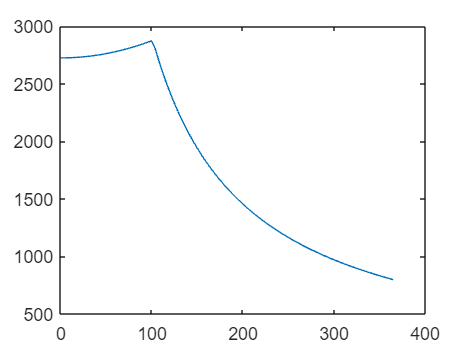

%Torque function test

a.gear_ratio = 1.3;   
a.Mass = 1000;          
Power = 350;        
Tmax = 185;
a.AA = 40;
n = 100;
v = linspace(0,v_max,n);
T = arrayfun(@(V) Torque(V,0,Tmax*1e3,Power*1e3,a), v);
plot(v*3.6,T)



%Define function to integrate
func_t = @(v) (a.Mass * a.delta ./ (Torque(v,0,Tmax*1e3,Power*1e3,a)*a.gear_ratio*a.efficiency/a.wheel_radius - tractive_force(0,v,0,a)));
v_ms = linspace(0,v_max,n);
plot(v_ms*3.6,arrayfun(@(V) func_t(V), v_ms))



%Integrate
t = integral(func_t,0,100/3.6)

t = 2.7208




%% implementing 1 foot rollout

ft = 0.3048;

func_s = @(v) v.*func_t(v);

v = linspace(0,10,n);

s = arrayfun(@(V) integral(func_s,0,V),v);

[ft_s, idft] = min(abs(s-ft));

v_ft = v(idft);

t_1ftrlt = integral(func_t,v_ft,100/3.6)

t_1ftrlt = 2.4741



%drive cycle

v_ms = linspace(0,v_max-10/3.6,n);
V_z = v_ms;
D_z = 1./(arrayfun(@(V) func_t(V), v_ms));
x_tot = arrayfun(@(V) integral(func_s,0,V),v_ms);

G_z = ones(n)

G_z =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

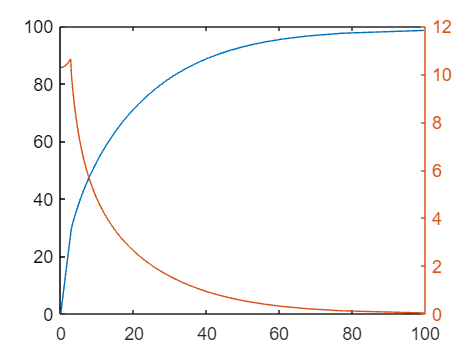


T_z = arrayfun(@(V) integral(func_t,0,V),v_ms);

close all
plot(T_z, V_z)
hold on
yyaxis right
plot(T_z,D_z)
hold off

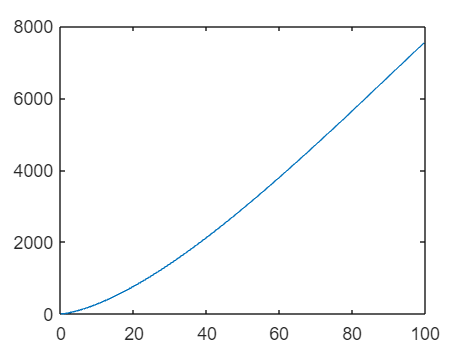



figure
plot(T_z,x_tot)



save ohdeargodimgonnadie D_z G_z T_z V_z


function [F_r] = tractive_force(alpha,V_ms,V_Sw_ms,a) 



%Physical constants
g       = 9.81;                     %Gravity        [m/s^2]
rho     = 1.293;                    %density of air [kg/m^3]

%Vehicle speed in m/s
% V_ms = V_kph./3.6; 

%Friction force 
F_f = (a.Mass * g + 0.5 * rho * a.Area_front * a.aero_efficiency* a.drag_coef * (V_ms-V_w_ms).^2)* a.friction_coef * cosd(alpha);          

%Gradeability force
F_g = a.Mass * g * sind(alpha);              

%Drag force
F_w = 0.5 * rho * a.Area_front * a.drag_coef * (V_ms-V_w_ms).^2; 

%Total tractive effort at a steady state
F_r = F_f + F_g + F_w; 

end



%Geting that torque curve
function [T] = Torque(V_ms, V_w_ms, Tmax, Pmax, a)


rho     = 1.293;                    %density of air [kg/m^3]

%traction coefficient
mu_p = 1.1;

%Determine motor speed for the driving speed.
% V_ms = V_kph./3.6;                          %speed in m/s
ww = V_ms./a.wheel_radius;  %wheel speed.
wp = ww*a.gear_ratio;        % motor speed

%Calculate tire limit
Fn = 9.81*a.Mass + a.AA*9.81 + 0.5 * rho * a.Area_front * a.aero_efficiency* a.drag_coef * (V_ms-V_w_ms).^2;  %Normal force %used simliar aero efficiency for f1
Ftmax = Fn * mu_p;                                                              %Max force on the tyre
Twtmax = Ftmax * a.wheel_radius;                                                %Max torque on the tyre
Tptmax = Twtmax / (a.gear_ratio*a.efficiency);                                  %Max torque on the motor

T = min([Pmax./wp,Tmax,Tptmax]);

end

%code that didnt really fit


% %Calculation for maximum gradeability;
% 
% F_maxgrade = tractive_force(10,100,M,g,f_r,rho,A_f,C_d,V_w_ms); 
% T_maxgrade = (F_maxgrade*r_w)/(i_g*n_d);
